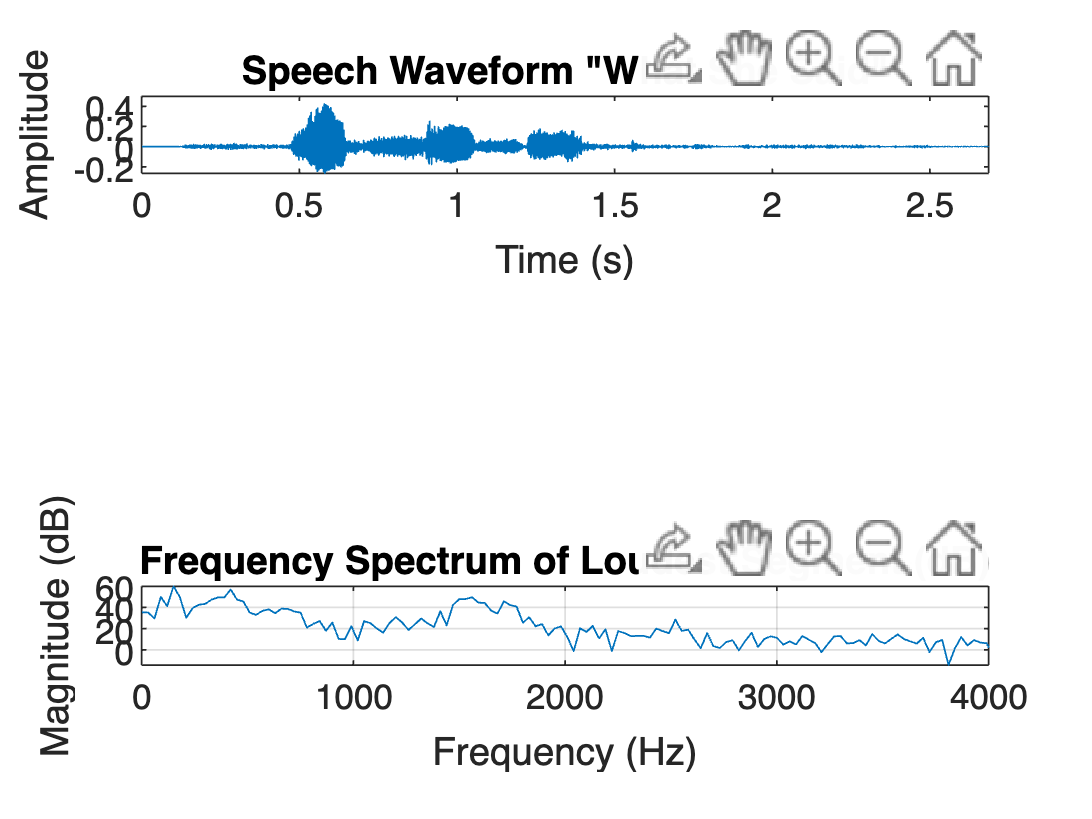

% Load your speech recording
[audio, fs] = audioread('whatshesaid.m4a');

% Ensure it is a mono signal
if size(audio, 2) > 1
    audio = audio(:, 1); % Use the left channel only
end

t = (0:length(audio)-1) / fs;

% Plot Waveform
figure;
subplot(3,1,1);
plot(t, audio);
title('Speech Waveform "What She Said"');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 max(t)]);

% Use the loudest segment
segment = audio(best_start:(best_start + segment_length - 1));

% FFT Calculation (Corrected)
f = (0:round(length(segment)/2)-1) * fs / length(segment);
Y = abs(fft(segment) / length(segment));
Y = Y(1:length(f)); % Only keep positive frequencies

% Pre-amplify for better visibility
Y = Y / max(Y); % Normalize
Y = Y * 1000;   % Amplify for visibility

% Plot Frequency Spectrum
subplot(3,1,3);
plot(f, 20 * log10(Y)); % Log scale for better visibility
title('Frequency Spectrum of Loudest Segment (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 4000]); % Only show up to 4000 Hz

grid on;

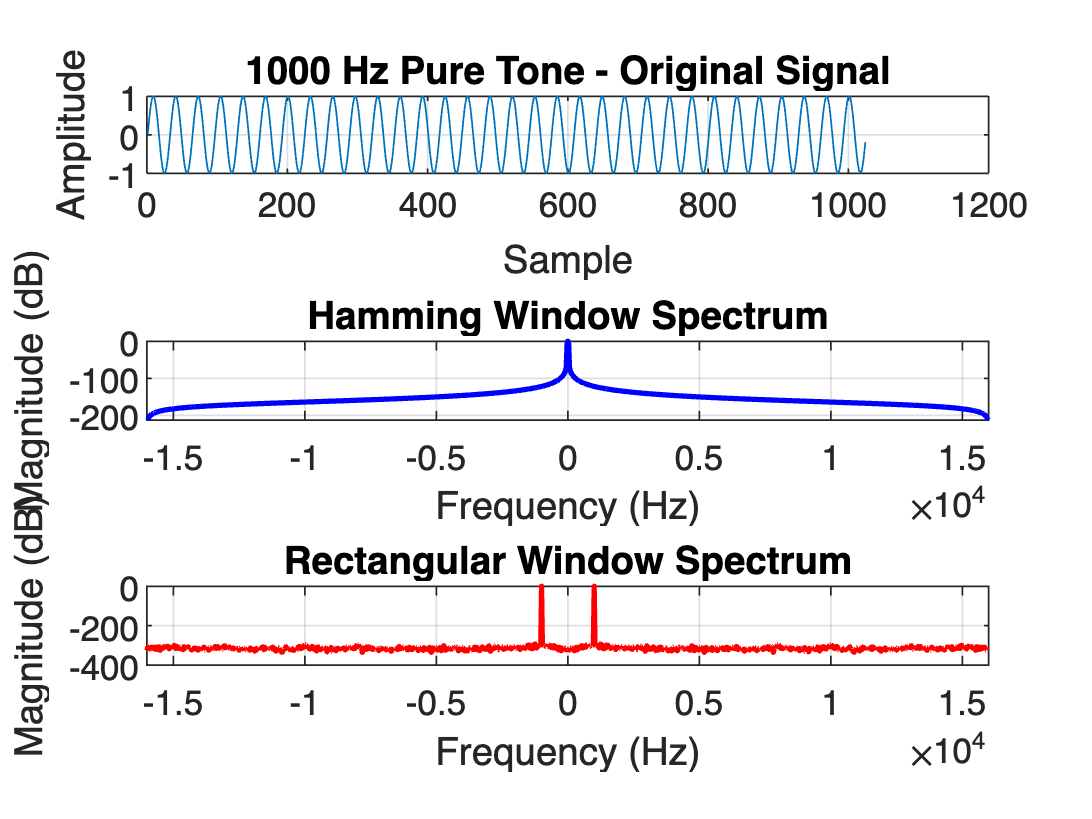

% === Short-Time Windowing Demonstration with 1000 Hz Pure Tone ===
fs = 32000;                     % Sampling rate
t = (0:1/fs:1-1/fs);            % Time vector for 1 second
signal = sin(2 * pi * 1000 * t); % 1000 Hz Pure Tone Signal

% Window Length (1024 samples)
N = 1024;
segment = signal(1:N);          % Use the first 1024 samples

% Apply Hamming and Rectangular Windows
hamming_window = hamming(N) .* segment;
rectangular_window = segment;   % Rectangular is just the raw segment

% Compute FFT (magnitude in dB)
f = (-N/2:N/2-1) * (fs / N);    % Frequency axis

hamming_spectrum = abs(fftshift(fft(hamming_window, N)));
rectangular_spectrum = abs(fftshift(fft(rectangular_window, N)));

% Normalize and Convert to dB
hamming_spectrum_db = 20 * log10(hamming_spectrum / max(hamming_spectrum));
rectangular_spectrum_db = 20 * log10(rectangular_spectrum / max(rectangular_spectrum));

% === Plotting ===
figure;
subplot(3,1,1);
plot(segment);
title('1000 Hz Pure Tone - Original Signal');
xlabel('Sample');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(f, hamming_spectrum_db, 'b', 'LineWidth', 1.5);
title('Hamming Window Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([-fs/2 fs/2]);
grid on;

subplot(3,1,3);
plot(f, rectangular_spectrum_db, 'r', 'LineWidth', 1.5);
title('Rectangular Window Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([-fs/2 fs/2]);
grid on;

% === Bandpass Filtering Demonstration with Speech Signal ===
% Load your speech recording
[audio, fs] = audioread('we were away a year ago_lrr.wav');
audio = audio(:, 1); % Use left channel if stereo

% Extract a short segment for visualization (first 0.5 seconds)
segment = audio(1:round(0.5 * fs));

% Generate high-frequency noise (5000 - 8000 Hz)
t = (0:length(segment)-1) / fs;
high_freq_noise = 0.5 * (sin(2 * pi * 6000 * t) + sin(2 * pi * 8000 * t));

% Add noise to the signal
noisy_signal = segment + high_freq_noise;

% Design a Bandpass Filter (300 - 3400 Hz)
bp_filter = designfilt('bandpassiir','FilterOrder',8, ...
                       'HalfPowerFrequency1',300,'HalfPowerFrequency2',3400, ...
                       'SampleRate',fs);

% Apply the Bandpass Filter
filtered_signal = filter(bp_filter, noisy_signal);

% === Plotting ===
figure;
subplot(3,1,1);
plot(t, noisy_signal);
title('Noisy Speech Signal (Speech + High-Frequency Noise)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, filtered_signal);
title('Bandpass Filtered Signal (300 - 3400 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Frequency Domain Visualization
f = (-fs/2:fs/length(noisy_signal):fs/2 - fs/length(noisy_signal));
original_spectrum = abs(fftshift(fft(noisy_signal)));
filtered_spectrum = abs(fftshift(fft(filtered_signal)));

subplot(3,1,3);
plot(f, original_spectrum, 'r', 'LineWidth', 1.5, 'DisplayName', 'Noisy Signal');
hold on;
plot(f, filtered_spectrum, 'b', 'LineWidth', 2.5, 'DisplayName', 'Filtered Signal');
xlim([-5000 5000]);
title('Frequency Domain - Before and After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Noisy Signal', 'Filtered Signal');
grid on;